# Proyecto Final 

## Mundial de Qatar

## Universidad Autonoma del Estado de Mexico

## Ingenieria en Computación

## Ciencia de los datos 

## Integrantes:

## Carlos Almazan Rodriguez 

## Aldo Rojas Gómez 

## Profesor: Asdrúbal López Chau 

## Noviembre 2022

## Conjunto de Datos

Este conjunto de datos muestra los pronosticos de cada equipo como es su nivel actual y como estan clasificados segun su empeño al haber clasificado al mundial 2022

## Descripción General

La **Copa Mundial de la** [**FIFA**](https://es.wikipedia.org/wiki/FIFA), también conocida como **Copa Mundial de Fútbol**, **Copa del Mundo** o simplemente **Mundial**, cuyo nombre original fue **Campeonato Mundial de Fútbol**, es el principal [torneo internacional](https://es.wikipedia.org/wiki/Anexo:Partidos_y_competiciones_internacionales_de_f%C3%BAtbol) oficial de [fútbol](https://es.wikipedia.org/wiki/F%C3%BAtbol) masculino a nivel de selecciones nacionales en el mundo,

 Este evento deportivo se realiza cada cuatro años desde 1930, con la excepción de 1942 y 1946, en los que se suspendió respectivamente debido al desarrollo y las consecuencias de la [Segunda Guerra Mundial](https://es.wikipedia.org/wiki/Segunda_Guerra_Mundial). Cuenta con dos etapas principales: un proceso clasificatorio en el que participan en la actualidad cerca de 200 selecciones nacionales y una fase final realizada cada cuatro años en una sede definida con anticipación en la que participan 32 equipos (48 a partir de la edición de 2026) durante un periodo cercano a un mes. El [balón oficial](https://es.wikipedia.org/wiki/Anexo:Balones_de_la_Copa_Mundial_de_F%C3%BAtbol) es fabricado por la compañía [alemana](https://es.wikipedia.org/wiki/Alemania) de equipamiento deportivo [Adidas](https://es.wikipedia.org/wiki/Adidas)

a sido realizada en 21 ocasiones, [Brasil](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Brasil) es la selección más exitosa, con cinco victorias; [Alemania](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Alemania) e [Italia](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Italia) le siguen con cuatro trofeos; [Argentina](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_la_Argentina), [Francia](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Francia) y [Uruguay](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_del_Uruguay) la han ganado dos veces, en tanto [Inglaterra](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Inglaterra) y [España](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Espa%C3%B1a) se han titulado campeones una vez

 Los equipos [europeos](https://es.wikipedia.org/wiki/UEFA) han ganado el título en doce ocasiones, mientras que los [sudamericanos](https://es.wikipedia.org/wiki/Confederaci%C3%B3n_Sudamericana_de_F%C3%BAtbol) lo han hecho en nueve. Solo dos equipos de otras confederaciones han llegado a semifinales: [Estados Unidos](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Estados_Unidos) en [1930](https://es.wikipedia.org/wiki/Copa_Mundial_de_F%C3%BAtbol_de_1930) y [Corea del Sur](https://es.wikipedia.org/wiki/Selecci%C3%B3n_de_f%C3%BAtbol_de_Corea_del_Sur) en [2002](https://es.wikipedia.org/wiki/Copa_Mundial_de_F%C3%BAtbol_de_2002).

## Preguntas

1 - ¿Qué equipo tiene mayor pronostico de ganar este mundial segun su desempeño a la clasificacion?

2 - ¿El nivel de posición del campo y sus porteros influyen en los partidos?

3 - ¿Cuales son los equipos con mayor posibilidad de ganar este mundial 2022?

4 - ¿Mexico podria jugar su quinto partido?

Graficamos el desempeño de cada equipo en el campo

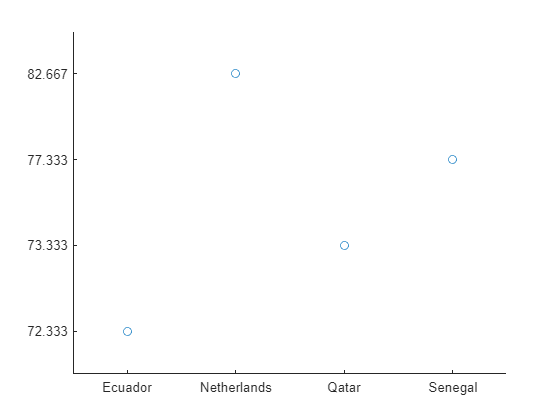

x = readtable("teams.csv");
%Graficamos el mejor equipo de cada Grupo
idx = x.group=="A";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

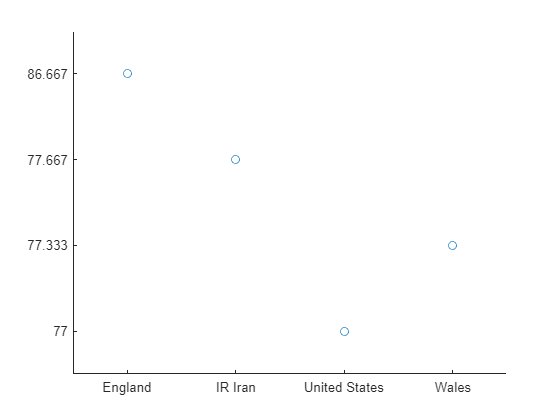

idx = x.group=="B";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

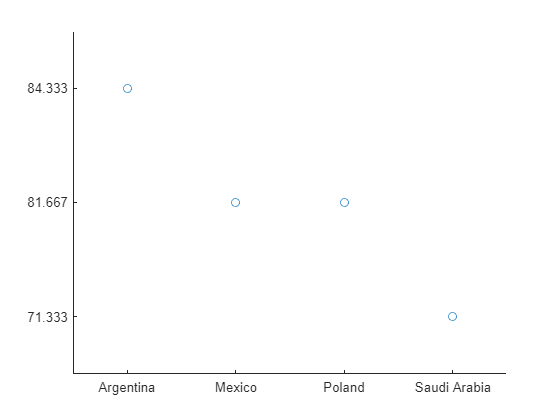

idx = x.group=="C";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

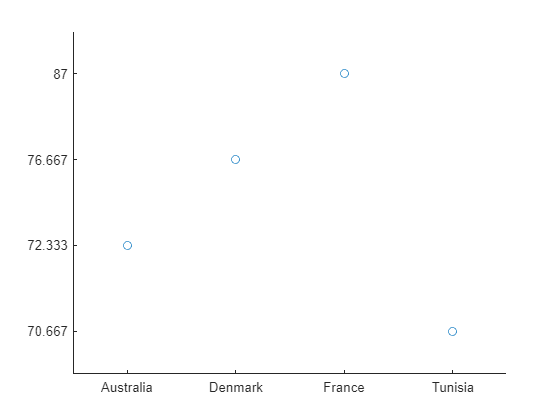

idx = x.group=="D";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

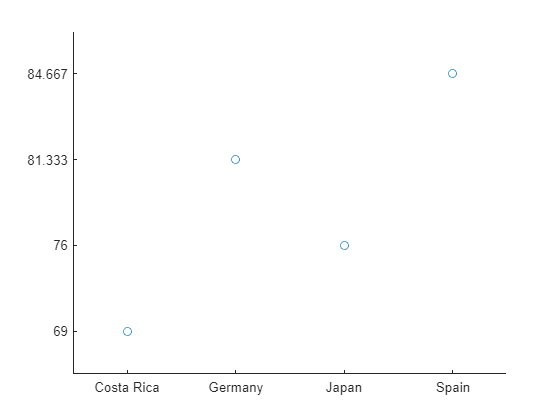

idx = x.group=="E";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

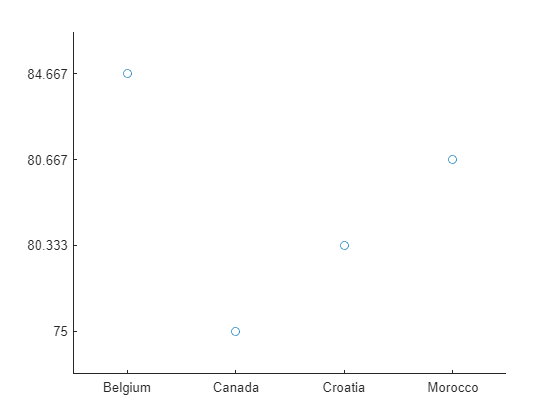

idx = x.group=="F";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

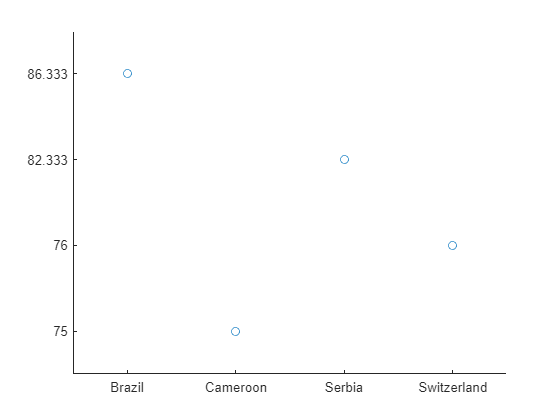

idx = x.group=="G";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

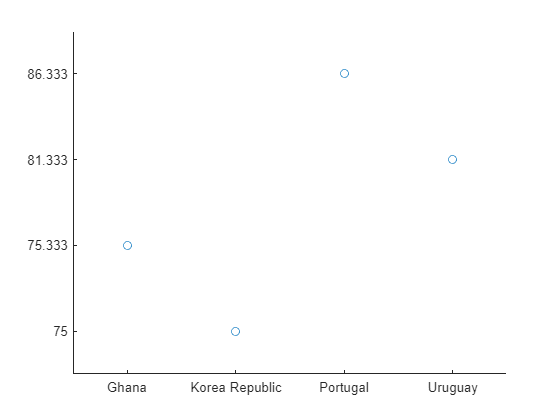

idx = x.group=="H";
scatter(categorical(x.home_team(idx)), categorical(x.home_team_mean_midfield_score(idx)))

## **Analisamos todos los datos de excel**

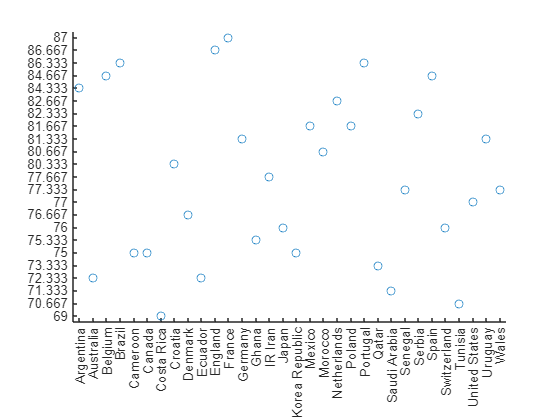

%Graficamos la dominacion de cada equipo en el centro del campo
scatter(categorical(x.home_team), categorical(x.away_team_mean_midfield_score))

## Peores equipos del mundial segun por su estadisticas

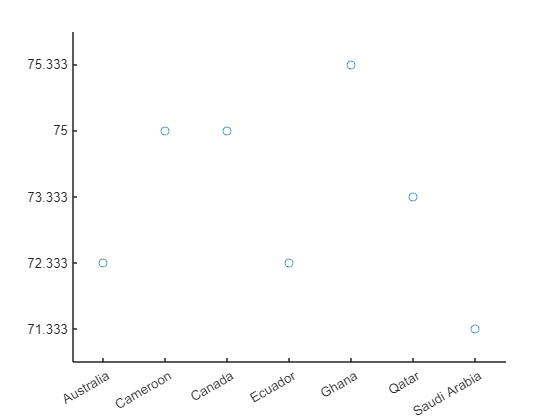

%Graficamos los 5 peores candidatos para ganar este mundial
ganador = x.home_team_fifa_rank>32;
scatter(categorical(x.home_team(ganador)), categorical(x.away_team_mean_midfield_score(ganador)))

## Mejores equipos de este mundial

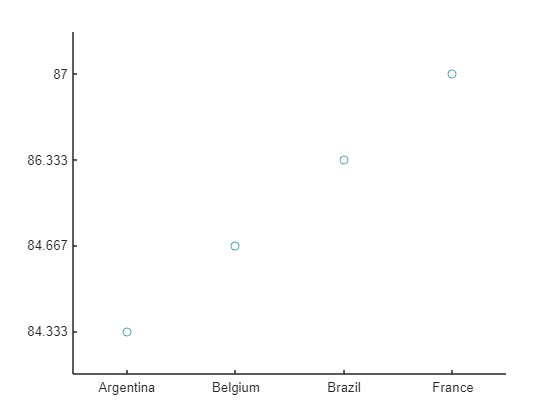


%Graficamos los 5 mejores candidatos para no ganar este mundial
ganador = x.home_team_fifa_rank<5;
scatter(categorical(x.home_team(ganador)), categorical(x.away_team_mean_midfield_score(ganador)))

## Quienes podrian ser los equipos 16 equipos para octavos

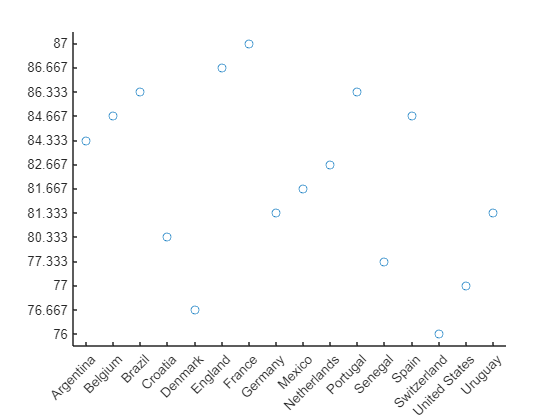

diezseis = x.home_team_fifa_rank<19;
scatter(categorical(x.home_team(diezseis)), categorical(x.away_team_mean_midfield_score(diezseis)))

## Que equipos podrian llegar a cuartos de final

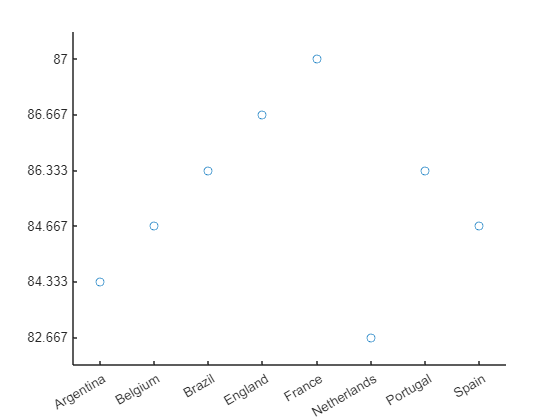

octavos = x.home_team_fifa_rank<10;
scatter(categorical(x.home_team(octavos)), categorical(x.away_team_mean_midfield_score(octavos)))

## Quien podiran llegar a la semifinal

semi = x.home_team_fifa_rank<5;
scatter(categorical(x.home_team(semi)), categorical(x.away_team_mean_midfield_score(semi)))

## Quien es el ganador de este mundial

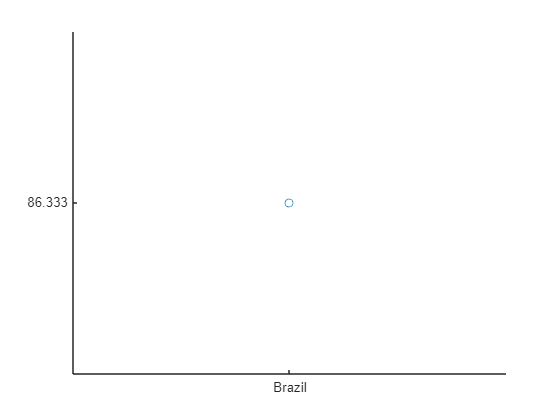

ganador = x.home_team_fifa_rank<2;
scatter(categorical(x.home_team(ganador)), categorical(x.away_team_mean_midfield_score(ganador)))

#### Hipotesis de Ji Cuadrada 

La prueba de Chi-Cuadrado es un procedimiento estadístico utilizado para determinar si existe una diferencia significativa entre los resultados esperados y los observados en una o más categorías.

Se trata de una prueva no parametrica que es utilizada por los investigadores para **examinar las diferencias entre variables categóricas en la misma población**

La idea básica de la prueba es que se comparan los valores de los datos reales con lo que se esperaría si la hipótesis nula fuera cierta.

De esta forma, se busca determinar si una diferencia entre los datos observados y los esperados se debe al azar, o si se debe a una relación entre las variables que se están estudiando. 

con respecto a la H0 (hipotesis nula) y H1(hipotesis alternativa)

H0 (hipotesis nula):los datos no estan relacionados   

H1(hipotesis alternativa) : los datos estan relacionados

tabla = grados de libertad 

chi2 = hipotesis nula

p = hipotesis alternativa

0.5 < se rechasa la hipotesis > 0.5 se hacepta la hipotesis

%relacion entre el rank del equipo y el rank del portero 
x = readtable("teams.csv");
[tabla,chi2,p] = crosstab(x.away_team_fifa_rank,x.home_team_fifa_rank)

tabla =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

chi2 = 992

p = 0.2374

%relacion entre el rank del equipo y el rank del portero 
x = readtable("teams.csv");
[tabla,chi2,p] = crosstab(x.home_team_fifa_rank,x.home_team_goalkeeper_score)

tabla =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0

chi2 = 608

p = 0.2853

%relacion entre el rank del equipo y el rank de la defensa del equipo
x = readtable("teams.csv");
[tabla,chi2,p] = crosstab(x.home_team_fifa_rank,x.home_team_mean_defense_score)

tabla =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1   

chi2 = 864.0000

p = 0.2517

%relacion entre el rank del equipo y el rank de la ofensiva del equipo
x = readtable("teams.csv");
[tabla,chi2,p] = crosstab(x.home_team_fifa_rank,x.home_team_mean_offense_score)

tabla =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0  

chi2 = 736

p = 0.2675

%relacion entre el rank del equipo y el rank del medio campista
x = readtable("teams.csv");
[tabla,chi2,p] = crosstab(x.home_team_fifa_rank,x.home_team_mean_midfield_score)

tabla =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0 

chi2 = 704.0000

p = 0.2718

## Hallazgos y Conclusiones 

El mayor pronostico para ganar este mundial segun su desempeño a la clasificacion es Brasil con un porcentaje de 86.333% de probabilidad de que asi sea actualizándose en vivo.

El nivel de posición del campo conjunto de sus porteros si influyen en los partidos ya que el porcentaje depende de su defensiva y ofensiva en cada partido ya jugado 

Los equipos con mayor posibilidad de ganar este mundial son Argentina, Belgica, Brasil y Francia en este mundial Qatar 2022

Mexico necesita un milagro para jugar el 5to partido ya que primero depende de otro equipo (en este caso Polonia) para que gane contra Argentina y Mexico ganar contra Arabia Saudito en el mejor de los casos posibles. despues de eso se enfrentaria contra Francia quien fue el Campeon Mundial en el año 2018 el cual hay una probabilidad minima de que llegue al 5to partido 

## De manera periódica, la **FIFA **actualiza su ranking y destaca a una selección por delante del resto. Hoy por hoy, según la federación madre del fútbol mundial, **Brasil **es el mejor equipo del mundo, por lo que aparece como el favorito a quedarse con el **Mundial de Qatar 2022**. Sin embargo, esto no funciona como una regla

**Más atrás aparecen Argentina, Francia, Inglaterra, Italia, España, Países Bajos y Portugal **